clear all; % liberta a memória do computador
nbit = 40000; % comprimento da sequencia binária, valor variável
R = 2e6; % taxa de transmissão em bit/s
N = 16; % nº de amostras por símbolo
fa = N*R; % frequência de amostragem
Ntempo = 32; % nº de símbolos a visualizar nos diagramas temporais

## 2.1 NRZ

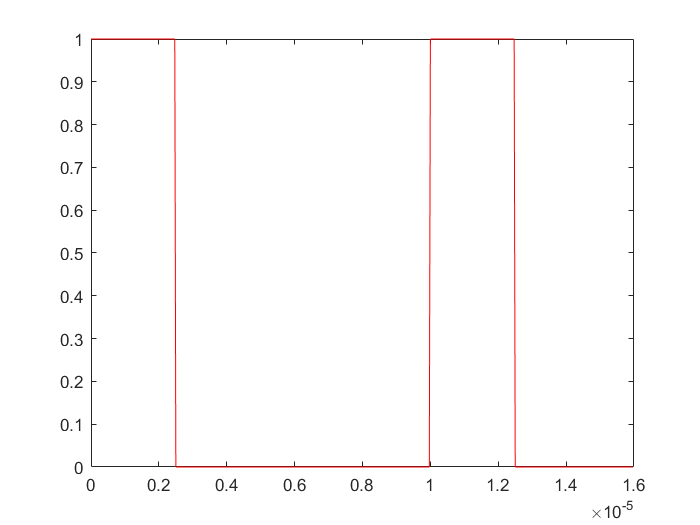

infb = [ones(1,5) zeros(1,15)]; % definição da palavra de 20 bits
inf = repmat(infb,1,floor(nbit/length(infb))); % sequência binária de tamanho nbit
[s_tx,t] = nrz(inf,R,N); % NRZ
figure(1)
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r');

fprintf('Valor médio = %4.2f V\n',mean(s_tx))

Valor médio = 0.25 V


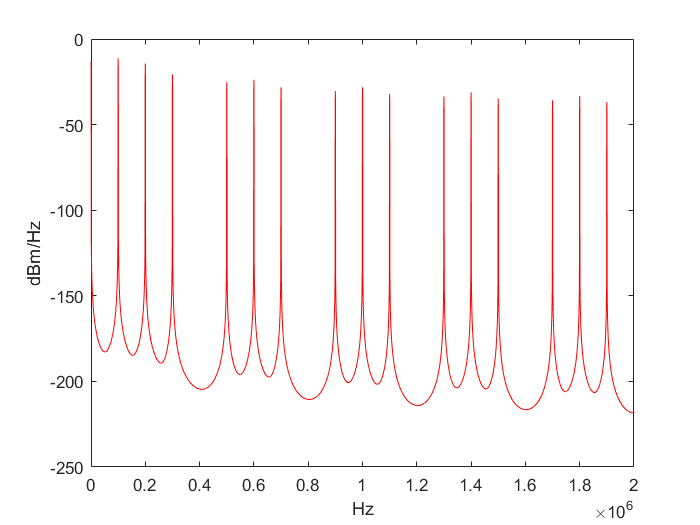


windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');
Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
figure(2)
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
xlim([0 2*10^6])

## 2.1.2

inf = randi([0 1],1,nbit); % seq. binária com igual prob. para '0' e '1'
[s_tx,t] = nrz(inf,R,N); % NRZ
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
eyediagram(s_tx(1:256*N),2*N); %diagrama de olho
fprintf('Valor médio = %4.2f V\n',mean(s_tx))

Valor médio = 0.50 V


windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');
Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
xlim([0 8*10^6])
% for f=0Hz
Max1=10*log10(max(Pxx(f>2e5))/1e-3)
% for f=(3/2)/THz
Max2=10*log10(max(Pxx(f>2e6))/1e-3)
Relation_Sim = Max1 - Max2

## 2.2 RZ, Manchester, AMI

inf = randi([0 1],1,nbit); % seq. binária com igual prob. para '0' e '1'
[s_tx,t] = rz(inf,R,N) % RZ
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
fprintf('Valor médio = %4.2f V\n',mean(s_tx))

windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');
Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
xlim([0 12*10^6])

inf = randi([0 1],1,nbit); % seq. binária com igual prob. para '0' e '1'
[s_tx,t] = manchester(inf,R,N) % BIfasico
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
fprintf('Valor médio = %4.2f V\n',mean(s_tx))

windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');
Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');

inf = randi([0 1],1,nbit); % seq. binária com igual prob. para '0' e '1'
[s_tx,t] = ami(inf,R,N) % BIfasico
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r'); % diag. temp. do sinal tx
fprintf('Valor médio = %4.2f V\n',mean(s_tx))

windowL = floor(length(s_tx)/10); % Segment length in Welch's method
windowT=hamming(windowL); % Hamming window type (Welch's method)
[Pxx,f] = pwelch(s_tx, windowT, windowL/2, windowL, fa, 'onesided');
Pxx=Pxx/2; % To compensate for the fact that function pwelch performs
% unilateral PSD
plot(f,10*log10(Pxx/1e-3),'r');
xlabel('Hz'); ylabel('dBm/Hz');
xlim([0 12*10^6])

## 3.1 Caracterizar sinal

fc=2e6;
[b,a] = butter(1,fc/(fa/2)); % Normalized frequency: f/(fa/2)
fvtool(b,a,'Analysis','freq')

## 3.1.1

f=2e6; % frequência
t=0:1/fa:nbit/fa; % vetor temporal
in = sin(2*pi*f*t); % sinusóide à entrada
n=10*floor(fa/f); % nº de ciclos a visualizar
figure(6), plot(t(1:n),in(1:n),'b'), grid on;
out = filter(b,a,in); % obter sinusóide à saída
hold on; plot(t(1:n),out(1:n),'r')
tSteadyState = t(t>=4e-6 & t<=4.5e-6);
inSteadyState = in(t>=4e-6 & t<=4.5e-6);
outSteadyState = out(t>=4e-6 & t<=4.5e-6);
t_maxIn = tSteadyState(inSteadyState == max(inSteadyState));
t_maxOut = tSteadyState(outSteadyState == max(outSteadyState));

tdiff=t_maxOut-t_maxIn

## 3.1.2

fvtool(b,a,'Analysis','freq')
Tr = 0.35/fc

## 3.2

in=nrz(inf,R,N);
out = filter(b,a,in);
ns=1:N*Ntempo;
plot(t(ns),in(ns),'b',t(ns),out(ns),'r'); grid on;
xlabel('t(s)'); legend('NRZ in','NRZ out');

## 3.2.1